# Modal Analysis of Soft Robot

#### Import all relevant files and build matrices

clear vars; close all; clc;

num_nodes = 1628;
alpha = 2.5; beta = 0.01;

% (Mass) M - Constant mass matrix
% (Stiffness) K - K(q_g) where q_g is resting eq under gravity
% (Damping) DAMP - alpha * M + beta * K (where alpha = 2.5, beta = 0.01)
% (Constraint matrix) H - H(q_g) is the input constraint/selection matrix
M = readmatrix("../M_actual.csv");
K = readmatrix("../K_0001.csv");
DAMP = alpha.*M + beta.*K;
H = readmatrix("../H_actual.csv");

% Recall: format of x is x = (v, q)
% This is the output configuration for figure 8!
% UNCOMMENT THIS IF YOU WANT TO SEE AMPLITUDES OF FIGURE 8
% vq_figureeight = readmatrix("../vq.csv").';
% q_figureeight = vq_figureeight(3*num_nodes+1:end, sim_length:end);

% Build C (output matrix)
output_node = 1354;
C = zeros(3, 3 * num_nodes);
C(1, 3*output_node + 1) = 1;
C(2, 3*output_node + 2) = 1;
C(3, 3*output_node + 3) = 1;

% Load trajectory data
%run('../modal_trajectory_data/decay/storeData.m'); % comment this line if decayData.mat is already available
%load('../modal_trajectory_data/decay/dataDecay.mat');

%run('../modal_trajectory_data/check_model/storeData.m'); % comment this line if decayData.mat is already available
load('../modal_trajectory_data/check_model/dataDecay.mat');

**Plot data**

nTraj = size(xData,1);
figure; 
subplot(3,1,1); hold on; grid on; box on; xlabel('$t$ [s]','Interpreter','latex'); ylabel('$x$ [mm]','Interpreter','latex');
subplot(3,1,2); hold on; grid on; box on; xlabel('$t$ [s]','Interpreter','latex'); ylabel('$y$ [mm]','Interpreter','latex');
subplot(3,1,3); hold on; grid on; box on; xlabel('$t$ [s]','Interpreter','latex'); ylabel('$z$ [mm]','Interpreter','latex');
for iTraj = 1:nTraj
    for iDir = [1 2 3]
    subplot(3,1,iDir);
    plot(xData{iTraj,1}, xData{iTraj,2}(3*output_node + iDir,:), 'Linewidth', 1)
    end
end
legend('dt = 1e-2', 'dt = 1e-3','dt = 1e-4')

**Compute conservative and damped modes**

[Wcons, A, Vcons, lambda] = linearpart(M, DAMP, K, 'nModes', 10, 'modeType', 'conservative');

   1.0e+03 *

    0.4002
    0.4152
    0.4488
    0.8505
    1.6569
    1.7535
    1.9379
    3.1423
    3.2181
    5.1441



%[Wcons, A, Vcons, lambda] = linearpart(M, DAMP, K, 'nModes', 10);

Ae = full(Wcons*A*Vcons); lambda
yDataCons = xData;
figure;
subplot(3,1,1); hold on; grid on; box on; xlabel('$t$','Interpreter','latex'); ylabel('$u_1$','Interpreter','latex');
subplot(3,1,2); hold on; grid on; box on; xlabel('$t$','Interpreter','latex'); ylabel('$u_2$','Interpreter','latex');
subplot(3,1,3); hold on; grid on; box on; xlabel('$t$','Interpreter','latex'); ylabel('$u_3$','Interpreter','latex');
for iTraj = 1:nTraj
    yDataCons{iTraj,2} = Wcons*xData{iTraj,2};
    for iDir = [1 2 3]
    subplot(3,1,iDir);
    plot(yDataCons{iTraj,1}, yDataCons{iTraj,2}(2*iDir - 1,:), 'Linewidth', 1)
    end
end
legend('dt = 1e-2', 'dt = 1e-3','dt = 1e-4')


figure; colororder(turbo(25))
iTraj = 1;
plot(yDataCons{iTraj,1}, yDataCons{iTraj,2}(1:2:end,:), 'Linewidth', 1)

**Plot trajectories (iplot represents initial displacement mode)**

First mode

iPlot = 1; modeRef = 1;
figure; hold on; grid on; box on; 
xlabel(['$u_' num2str(modeRef) '$'],'Interpreter','latex'); 
ylabel(['$\dot{u}_' num2str(modeRef) '$'],'Interpreter','latex'); 
zlabel('$u_3$','Interpreter','latex');
plot3(yDataCons{iPlot,2}(2*modeRef - 1,:), yDataCons{iPlot,2}(2*modeRef,:), xData{iPlot,2}(3*output_node + 1,:), 'LineWidth', 1)
view(3)

Second mode

iPlot = 2; modeRef = 1;
hold on; grid on; box on; 
xlabel(['$u_' num2str(modeRef) '$'],'Interpreter','latex'); 
ylabel(['$\dot{u}_' num2str(modeRef) '$'],'Interpreter','latex'); 
zlabel('$u_1$','Interpreter','latex');
plot3(yDataCons{iPlot,2}(2*modeRef - 1,:), yDataCons{iPlot,2}(2*modeRef,:), xData{iPlot,2}(3*output_node + 1,:), 'LineWidth', 1)
view(3)

Third mode

iPlot = 3; modeRef = 1;
hold on; grid on; box on; 
xlabel(['$u_' num2str(modeRef) '$'],'Interpreter','latex'); 
ylabel(['$\dot{u}_' num2str(modeRef) '$'],'Interpreter','latex'); 
zlabel('$x$','Interpreter','latex');
plot3(yDataCons{iPlot,2}(2*modeRef - 1,:), yDataCons{iPlot,2}(2*modeRef,:), xData{iPlot,2}(3*output_node + 1,:), 'LineWidth', 1)
legend('dt = 1e-2', 'dt = 1e-3','dt = 1e-4');
view(3)

Full modes

[VdampedTemp,DdampedV] = eigs(A, 6, 'smallestabs');
Vdamped = VdampedTemp./sum(VdampedTemp.*conj(VdampedTemp),1);
[WdampedTemp,DdampedW] = eigs(A', 6, 'smallestabs');
Wdamped = (transpose(WdampedTemp)*Vdamped)\transpose(WdampedTemp);
Wdamped*Vdamped

ans =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i
   0.0000 - 0.0000i   1.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i
  -0.0000 + 0.0000i   0.0000 - 0.0000i   1.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 + 0.0000i
  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   1.0000 - 0.0000i


full(Wdamped*A*Vdamped)

ans =   -3.2510 -19.7392i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i
  -0.0000 + 0.0000i  -3.2510 +19.7392i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -3.3258 -20.1025i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -3.3258 +20.1025i   0.0000 - 0.0000i  -0.0000 - 0.0000i
  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -3.4940 -20.8950i   0.0000 + 0.0000i
   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -3.4940 +20.8950i



yDataDamp = xData;
figure;
subplot(3,1,1); hold on; grid on; box on; xlabel('$t$','Interpreter','latex'); ylabel('Re($\xi_1$)','Interpreter','latex');
subplot(3,1,2); hold on; grid on; box on; xlabel('$t$','Interpreter','latex'); ylabel('Re($\xi_2$)','Interpreter','latex');
subplot(3,1,3); hold on; grid on; box on; xlabel('$t$','Interpreter','latex'); ylabel('Re($\xi_3$)','Interpreter','latex');
for iTraj = 1:nTraj
    yDataDamp{iTraj,2} = Wdamped*xData{iTraj,2};
    for iDir = [1 2 3]
    subplot(3,1,iDir);
    plot(yDataDamp{iTraj,1}, real(yDataDamp{iTraj,2}(2*iDir - 1,:)), 'Linewidth', 1)
    end
end
legend('Mode 1','Mode 2','Mode 2','Mode 1-2','Mode 1-3','Mode 2-3')

**Plot trajectories**

First mode

iPlot = 1; modeRef = 1;
figure; hold on; grid on; box on; 
xlabel(['Re($\xi_' num2str(modeRef) '$)'],'Interpreter','latex'); 
ylabel(['Im($\xi_' num2str(modeRef) '$)'],'Interpreter','latex'); 
xlabel(['Re($\xi_' num2str(1) '$)'],'Interpreter','latex'); 
%plot3(real(yDataDamp{iPlot,2}(2*modeRef - 1,:)), imag(yDataDamp{iPlot,2}(2*modeRef -1,:)), real(yDataDamp{iPlot,2}(1,:)), 'LineWidth', 1)
plot3(real(yDataDamp{iPlot,2}(2*modeRef - 1,:)), imag(yDataDamp{iPlot,2}(2*modeRef -1,:)), xData{iPlot,2}(3*output_node + 1,:), 'LineWidth', 1)
view(3)

Second mode

iPlot = 2; modeRef = 1;
hold on; grid on; box on; 
xlabel(['Re($\xi_' num2str(modeRef) '$)'],'Interpreter','latex'); 
ylabel(['Im($\xi_' num2str(modeRef) '$)'],'Interpreter','latex'); 
zlabel('$x$','Interpreter','latex');
%plot3(real(yDataDamp{iPlot,2}(2*modeRef - 1,:)), imag(yDataDamp{iPlot,2}(2*modeRef -1,:)), real(yDataDamp{iPlot,2}(1,:)), 'LineWidth', 1)
plot3(real(yDataDamp{iPlot,2}(2*modeRef - 1,:)), imag(yDataDamp{iPlot,2}(2*modeRef -1,:)), xData{iPlot,2}(3*output_node + 1,:), 'LineWidth', 1)
view(3)

Third mode

iPlot = 3; modeRef = 1;
hold on; grid on; box on; 
xlabel(['Re($\xi_' num2str(modeRef) '$)'],'Interpreter','latex'); 
ylabel(['Im($\xi_' num2str(modeRef) '$)'],'Interpreter','latex'); 
zlabel('$x$','Interpreter','latex');

%plot3(real(yDataDamp{iPlot,2}(2*modeRef - 1,:)), imag(yDataDamp{iPlot,2}(2*modeRef -1,:)), real(yDataDamp{iPlot,2}(1,:)), 'LineWidth', 1)
plot3(real(yDataDamp{iPlot,2}(2*modeRef - 1,:)), imag(yDataDamp{iPlot,2}(2*modeRef -1,:)), xData{iPlot,2}(3*output_node + 1,:), 'LineWidth', 1)

Undefined variable yDataDamp.

legend('dt = 1e-2', 'dt = 1e-3','dt = 1e-4')
view(3)

## Check Empirical Modes

**Setup**

M = readmatrix("../M_actual.csv");
num_nodes = 1628;

q_mode1 = readmatrix("../modal_trajectory_data/check_model/empiricalModes/mode1.csv");
q_mode2 = readmatrix("../modal_trajectory_data/check_model/empiricalModes/mode2.csv");
q_mode3 = readmatrix("../modal_trajectory_data/check_model/empiricalModes/mode3.csv");

q_equilibrium = readmatrix("../modal_trajectory_data/check_model/empiricalModes/q_equilibrium.csv");

load('../modal_trajectory_data/check_model/empiricalModes/dataDecay.mat')

PSI = orthogonalizeGramSchmidt([q_mode1, q_mode2, q_mode3]);
[W, V] = projectionMatrix(M,PSI);

% Recall: format of x is x = (v, q)
% This is the output configuration for figure 8!
vq = readmatrix("../vq.csv").';
q = vq(3*num_nodes+1:end, 300:end);

% Actual output of system
z = readmatrix("../z.csv").';

% Build C (output matrix)
output_node = 1354;
C = zeros(3, 3 * num_nodes);
C(1, 3*output_node + 1) = 1;
C(2, 3*output_node + 2) = 1;
C(3, 3*output_node + 3) = 1;

**Check projection of output onto empirical modes**

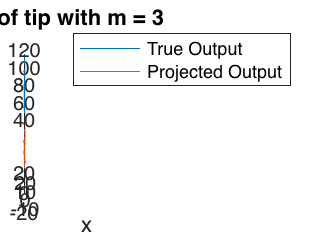

num_modes = 3;
% Form projection matrix
PI = PSI(:,1:num_modes) * PSI(:,1:num_modes).';

% Get projected output
q_proj = PI * q;
z_proj = C * q_proj; % Just the tip

% Reformat actual z (currently (v, q))
z_true = z(4:end, :);

% plot output after projection onto subspace
figure();
plot3(z_true(1, :), z_true(2, :), z_true(3, :))
hold on;
plot3(z_proj(1, :), z_proj(2, :), z_proj(3, :))
legend('True Output', 'Projected Output');
xlabel('x'); ylabel('y'); zlabel('z');
zlim([30, 130]);
str = sprintf('Trajectory of tip with m = %d', num_modes);
title(str)

**PCA of Decay Trajectory Data**

% only 2 modal initial conditions, 10ms sampling
%trajectories = readmatrix('../modal_trajectory_data/check_model/traj_data.csv');

% 3 modal initial conditions, 20ms sampling
%trajectories = readmatrix('../modal_trajectory_data/check_model/traj_data2.csv');

% PCA on q only
trajectories = readmatrix('../modal_trajectory_data/check_model/q_traj_data.csv');
 

Nt = size(trajectories, 1);
normed_trajectories = (trajectories - repmat(mean(trajectories, 1), Nt, 1))/sqrt(Nt - 1);
%[V, S] = PCA(normed_trajectories.', 500);
[V, S] = PCA(normed_trajectories.', 100);

**Plot singular value decay**

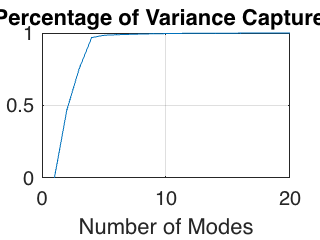

maxNumModes = 20;
modes = linspace(1, maxNumModes, maxNumModes);
energyFunc = @(x) sum(S(x:end).^2) / sum(S.^2);

figure;
plot(modes, 1 - arrayfun(energyFunc, modes));
grid on;
title('Percentage of Variance Captured');
xlabel('Number of Modes');